# Demonstration of DE Analysis and Marker Gene Identification Functions in scGEAToolbox

## Load example data set, X

cdgea; % set working directory
load example_data/markergeneident_demo X genelist s_tsne

## Group cells into clusters (k=6)

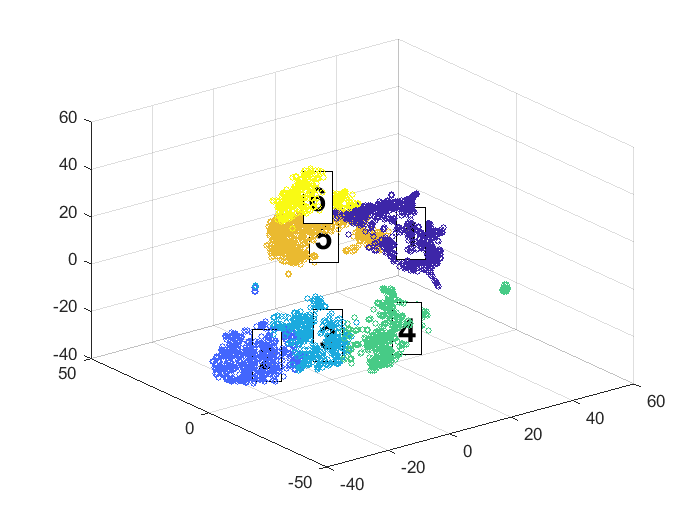

figure;
rng(1234)
cluster_kmedoids=sc_clustshow(s_tsne,6,'type','kmedoids');

## Identify marker genes for cluster #4

gmarkers=sc_pickmarkers(X,genelist,cluster_kmedoids,4);

## Show expression level of top 9 marker genes

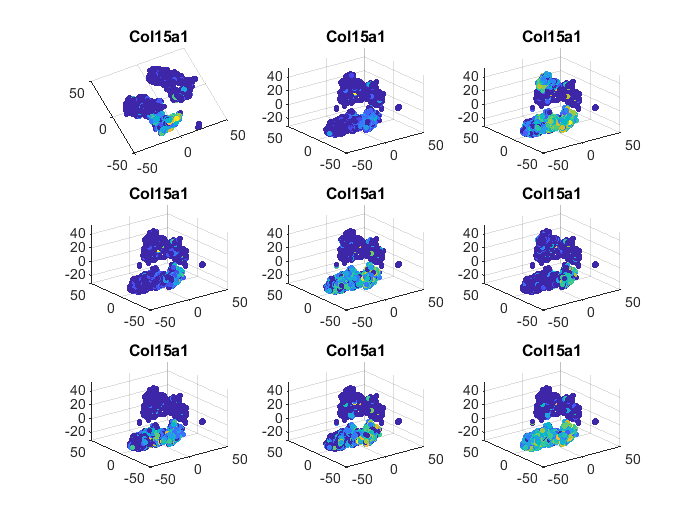

figure;
for k=1:9
    subplot(3,3,k)
    scatter3(s_tsne(:,1),s_tsne(:,2), s_tsne(:,3), 10,...
    log(1+X(genelist==gmarkers(k),:)), 'filled');
    title(g)
end
subplot(3,3,1)
view([-25 90])

## Show expression level of the top marker gene

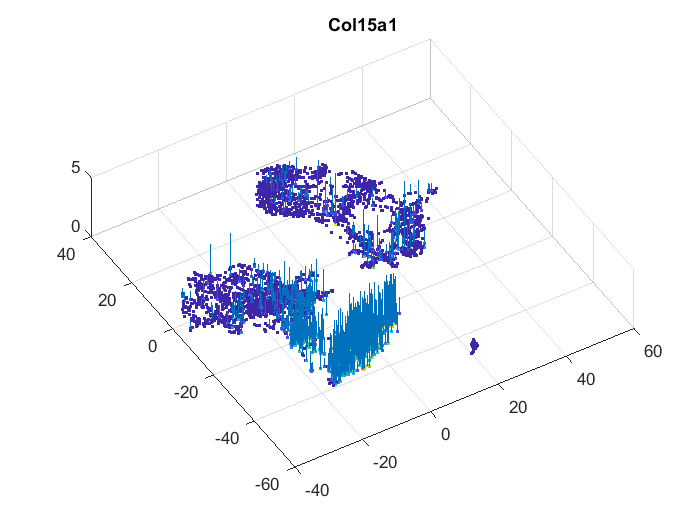

figure;
g=gmarkers(1);
sc_stemscatter(s_tsne(:,1), s_tsne(:,2), log(1+X(genelist==g,:)));
title(g)
view([-31.03 77.60])

## Determine cell type for each cluster using marker genes (collected by PanglaoDB)

Tct=sc_celltypes(X,genelist,cluster_kmedoids)

Tct = 10×12 table
           C1_Cell_Type           C1_CTA_Score           C2_Cell_Type            C2_CTA_Score           C3_Cell_Type            C3_CTA_Score                     C4_Cell_Type                     C4_CTA_Score            C5_Cell_Type             C5_CTA_Score            C6_Cell_Type             C6_CTA_Score
    __________________________    ____________    ___________________________    ____________    ___________________________    ____________    ______________________________________________    ____________    _____________________________    ____________    _____________________________

## The End